%hello
% clear;
% Th = readtable('sa-household-2019.csv')

Th = 19649×215 table
      uqnr       personnr       psu             prov          head_popgrp      head_sex     head_age                                              HSG_MAIND                                                      HSG_ROOF                    HSG_WALLS                HSG_FLOOR             HSG_COND_WALL              HSG_COND_ROOF             HSG_COND_FLOOR         HSG_RM_OPEN    HSG_RM_CLOSE    HSG_RM_BEDR    HSG_RM_MULTI    HSG_RM_KITCH    HSG_RM_TOIL    HSG_RM_BATH    HSG_RM_OTHR    HSG_RM_TOT             HSG_TENURE                  HSG_Rent            

% 
% % ijmp = [0;diff(T.uqnr)~=0];
% [~,uniqueIdx] = unique(Th.uqnr, 'first');
% Th = Th(uniqueIdx, :);
% uniqueIdx = [];
% 
% % Step 2: Remove columns from household table that already exist in person table
% Tp = readtable('sa-person-2019.csv')

Tp = 68986×149 table
      uqnr       personnr       psu             prov          Four_by_Four       Sex        age       age_grp1         Population                          HHC_RELATIONSHIP                                                            HHC_MARITAL                                              SPOUSE             SPOUSE_NAME        HHC_FATH_ALIVE      HHC_FATH_PARTHH        HHC_FATH_NAME       HHC_MOTH_ALIVE      HHC_MOTH_PARTHH        HHC_MOTH_NAME                                                             Education                                                              ECD_CHLDATT            ECD_NOTATT

% commonVars = intersect(Tp.Properties.VariableNames, ...
%                        Th.Properties.VariableNames);
% 
% % Keep only new columns + 'uqnr' for merging
% varsToAdd = setdiff(Th.Properties.VariableNames, commonVars);
% Th = Th(:, ['uqnr', varsToAdd]);
% 
% % Step 3: Perform a left join based on 'uqnr'
% T_merged = join(Tp, Th, 'Keys', 'uqnr');
% 
% Tp = []


Tp =

     []



% Th = []


Th =

     []



% 
% % Step 4 (optional): Write result to a new CSV file
% writetable(T_merged, 'merged-person-household.csv');

T = readtable('merged-person-household.csv');

% T_tb = To(strcmp(To.HLT_CHRONIC_TB, 'Yes'),:)
T_hiv = T(strcmp(T.HLT_CHRONIC_HIV, 'Yes'),:);

T_hiv = 2138×357 table
      uqnr       personnr       psu             prov          Four_by_Four       Sex        age       age_grp1           Population                             HHC_RELATIONSHIP                                                            HHC_MARITAL                                              SPOUSE             SPOUSE_NAME        HHC_FATH_ALIVE     HHC_FATH_PARTHH        HHC_FATH_NAME       HHC_MOTH_ALIVE     HHC_MOTH_PARTHH        HHC_MOTH_NAME                                                             Education                                                              ECD_CHLDATT            ECD_NOTAT

% T_nohiv = T(strcmp(T.HLT_CHRONIC_HIV, 'No'),:)

T = T_hiv

T = 2138×357 table
      uqnr       personnr       psu             prov          Four_by_Four       Sex        age       age_grp1           Population                             HHC_RELATIONSHIP                                                            HHC_MARITAL                                              SPOUSE             SPOUSE_NAME        HHC_FATH_ALIVE     HHC_FATH_PARTHH        HHC_FATH_NAME       HHC_MOTH_ALIVE     HHC_MOTH_PARTHH        HHC_MOTH_NAME                                                             Education                                                              ECD_CHLDATT            ECD_NOTATT

T_used = T;

% Split classes
minority = T(strcmp(T.HLT_CHRONIC_TB, 'Yes'),:);
majority = T(strcmp(T.HLT_CHRONIC_TB, 'No'),:);
rng=2

rng = 2


% Randomly downsample majority
idx = randperm(height(majority), floor(1.4*height(minority)));
majority_down = majority(idx, :);

% Combine balanced table
T = [minority; majority_down];

responseVar = 'HLT_CHRONIC_TB';
prefixes = {'HLT_','SAN_', 'FIN_INC_', 'chld', 'ad60', 'DSB_'}

prefixes = 1×6 cell array
    {'HLT_'}    {'SAN_'}    {'FIN_INC_'}    {'chld'}    {'ad60'}    {'DSB_'}


% exceptions
excludeVars = {responseVar, 'HLT_GENHEALTH', 'HLT_ILLNESS_SCBLOOD','HLT_CONSULT'};
includeVars = {'Population', 'age', 'Sex', 'prov',...
    'LSM_CAT', ...
    'HNW_HLTFAC', ...
    'HNW_NEAREST', ...
    'FSD_Hung_Adult', ...
    'FSD_Hung_Child', ...
    'FSD_WORRIED', ...
    'FSD_HEALTHY', ...
    'FSD_FEWFOODS', ...
    'FSD_HUNGRY', ...
    'AGR_Agri', ...
    'HWL_STATUS', ... % poverty status
    'HWL_Assets_ac', ...
    'hholdsz', ...
    'onemed_hh', ...
    'LAB_SALARY_hh', ...
    'soc_grant_hh', ...
    'totmhinc', ... % household income
    'undisab_hh', ...
    'disab_hh', ...
    'sevdisab_hh', ...
    };
% housing condition? water supply?

predictorVars = {};
varNames = T.Properties.VariableNames;
for i = 1:length(varNames)
    % Check if any prefix matches the start of the variable name
    for j = 1:length(prefixes)
        if (startsWith(varNames{i}, prefixes{j}) || ismember(varNames{i},includeVars)) && ~ismember(varNames{i},excludeVars)
            predictorVars{end+1} = varNames{i};
            break;  % Stop checking once a match is found
        end
    end
end

% GENHEALTH and ILLNESS_SCBLOOD are symptoms of TB
% LAB_SALARY and LAB_STO have most entries not reported
% EDU_RSNN includes illness and is very specific for education (reason for
% non-attendance, presumably at educational institution)
% excludeVars = {responseVar, 'HLT_GENHEALTH', 'HLT_ILLNESS_SCBLOOD', 'LAB_SALARY', 'LAB_STO', 'EDU_RSNN',...
    % 'HLT_CONSULT', 'LAB_GOVPROG'}; % TB = bad health, these are correlated
% Use all other columns as predictors
% predictorVars = setdiff(T.Properties.VariableNames, excludeVars);

% hltVarLocs = contains(predictorVars, 'HLT');
% predictorVars = predictorVars(hltVarLocs);

% Calculate class weights manually (inverse frequency)
classNames = categories(categorical(T.HLT_CHRONIC_TB))

classNames = 2×1 cell array
    {'No' }
    {'Yes'}


counts = [sum(strcmp(T.HLT_CHRONIC_TB, 'No')), sum(strcmp(T.HLT_CHRONIC_TB, 'Yes'))] 

counts =    124    89


total = sum(counts)

total = 213

weights = total ./ (length(counts) * counts)  % Inverse of frequency

weights =     0.8589    1.1966



% Create a cost matrix (optional alternative)
costMatrix = [0 weights(2); weights(1) 0];  % Cost of misclassifying each class
% Fit decision tree classifier
model = fitctree(T, responseVar, ...
    'PredictorNames', predictorVars, ...
    'ResponseName', responseVar, 'MinLeafSize',12, ...
    'ClassNames', classNames, 'cost', costMatrix);%, 'CrossVal','on');

% Fit decision tree classifier
% treeModel = fitctree(T, responseVar, ...
%     'PredictorNames', predictorVars, ...
%     'ResponseName', responseVar, 'MaxNumSplits',15);%, 'CrossVal','on');

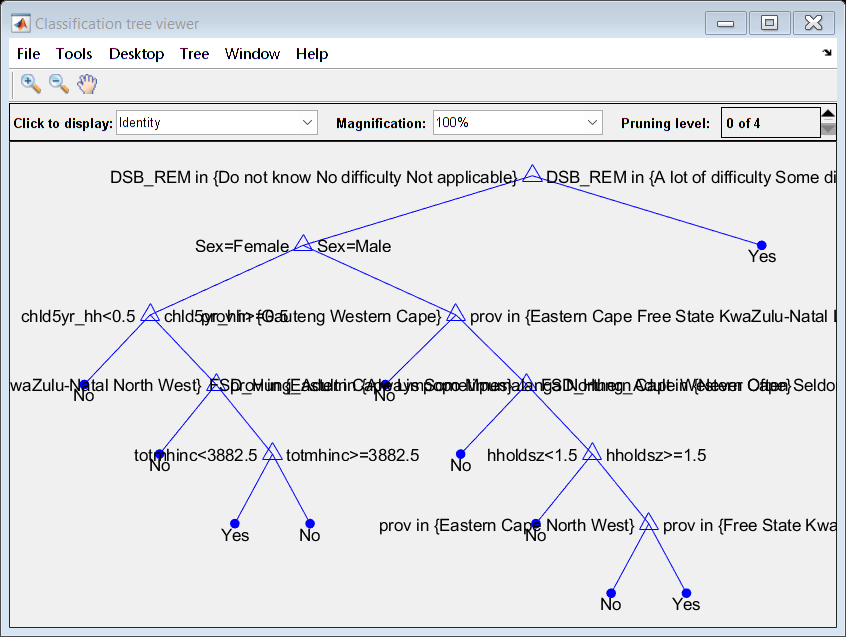

% classError = kfoldLoss(treeModel)
% model = treeModel.Trained{1};

view(model, 'Mode', 'graph');

% Predict on the training set
predictedLabels = predict(model, T_used);

% Compare with actual labels
cm = confusionmat(T_used.HLT_CHRONIC_TB, predictedLabels)

cm =         1568         481
          41          48


tp = cm(1,1)

tp = 1568

fn = cm(1,2)

fn = 481

fp = cm(2,1)

fp = 41

tn = cm(2,2)

tn = 48


accuracy = (tp+tn)/(tp+tn+fp+fn)

accuracy = 0.7558

precision = tp/(tp+fp)

precision = 0.9745

recall = tp/(tp+fn)

recall = 0.7653

f1 = 2*precision*recall/(precision+recall)

f1 = 0.8573

specificity = tn/(tn+fp)

specificity = 0.5393

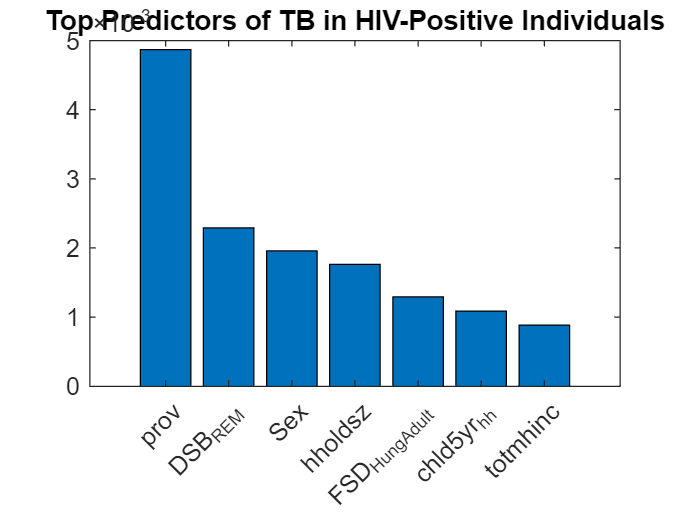

% Compute importance of each predictor
importance = predictorImportance(model);


% Plot feature importance
figure;
% Sort values descending
[sortedValues, sortIdx] = sort(importance, 'descend');
takeFirst = find(sortedValues == 0, 1, 'first') - 1;
sortedLabels = predictorVars(sortIdx(1:takeFirst));

bar(sortedValues(1:takeFirst))
set(gca, 'XTickLabel', sortedLabels, 'XTickLabelRotation', 45)
title('Top Predictors of TB in HIV-Positive Individuals')